clc;
clear all;

% Choose modulation order and format
MOD_ORDER = 16;
% 
MODULATION_FORMAT = 'QAM';

CYCLIC_PREFIX_LENGTH = 1/8; % Given as a ratio of symbol length

num_subcarriers_vals = (((1:1:300)/CYCLIC_PREFIX_LENGTH) - 2)/2;

total_num_symbols_desired = 1e6;

PAPR_values = zeros([1, length(num_subcarriers_vals)]);

for index = 1:1:length(num_subcarriers_vals)
    
    num_symbols_per_subcarrier = round(total_num_symbols_desired/num_subcarriers_vals(index));
    
    assert(mod((2+2*num_subcarriers_vals(index))*CYCLIC_PREFIX_LENGTH,1) == 0)

    [modulated_signal, symbol_stream] = generateRandModSignal(num_symbols_per_subcarrier, MOD_ORDER, num_subcarriers_vals(index), MODULATION_FORMAT);
    ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);
    PAPR_values(index) = calculatePAPR(ofdm_signal);
end

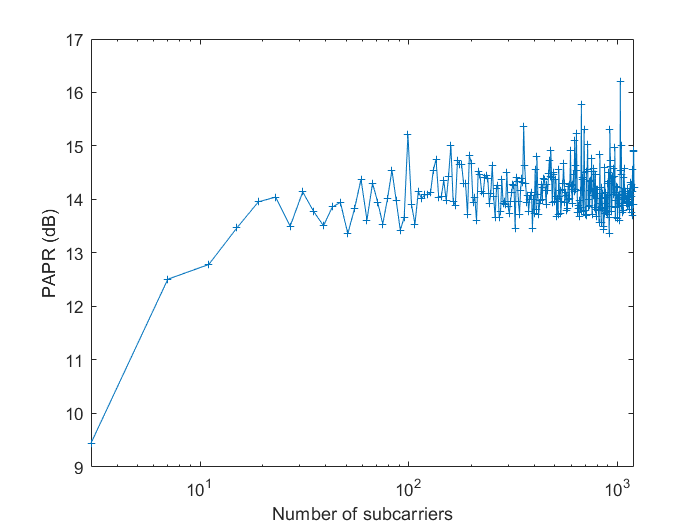

PAPR_plot = semilogx(num_subcarriers_vals, PAPR_values, '-+');
xlim([3, num_subcarriers_vals(end)])
PAPR_plot.MarkerSize = 4;
ylabel('PAPR (dB)');
xlabel('Number of subcarriers')

filename = strcat('PAPR_vs_subcarrier_number_', num2str(MOD_ORDER), '_', MODULATION_FORMAT, '_', timestampString());
saveas(gcf, filename, 'epsc')

% OFDM_SYMBOL_SIZE = (2 + 2*NUM_SUBCARRIERS)*(1 + CYCLIC_PREFIX_LENGTH);


% ofdm_signal_reshaped = reshape(ofdm_signal, OFDM_SYMBOL_SIZE, []);
% num_PAPR_values = size(ofdm_signal_reshaped,2);
% 
% PAPR_values = zeros([1,num_PAPR_values]);
% for index = 1:1:num_PAPR_values
%     PAPR_values(index) = calculatePAPR(ofdm_signal_reshaped(:,index));
% end